# Hashin Shtrikman Bounds 

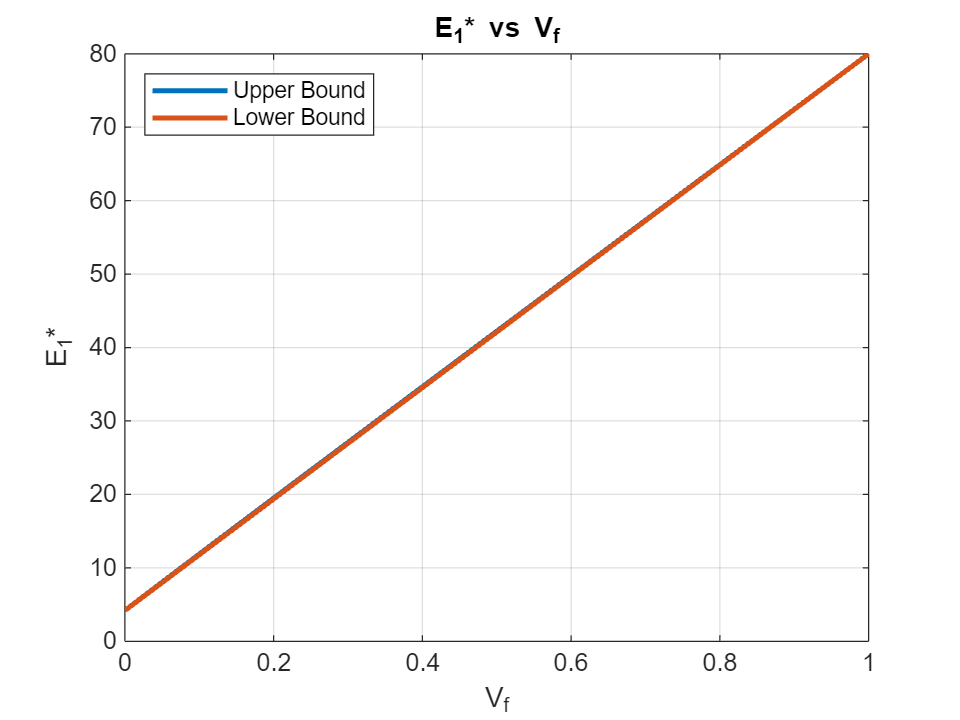

clc;clear;
syms Vf
Vf_val = linspace(0,1,101);

E_f = 80;
G_f = 33.33;
v_f = 0.2;
K_f = E_f/(3*(1-2*v_f));

E_m = 4.2;
v_m = 0.34;
a_m = 45;
G_m = E_m/(2*(1+v_m));
K_m = E_m/(3*(1-2*v_m));

%E1
E1_minus = (E_m * (1-Vf)) + (E_f * Vf) + ((4 * ((v_f - v_m)^2) * Vf * (1-Vf)) /(((1-Vf) / K_f) + (Vf / K_m) + (1 / G_m)));
E1_minus = double(subs(E1_minus,Vf_val));
E1_plus = (E_m * (1-Vf)) + (E_f * Vf) + ((4 * ((v_f - v_m)^2) * Vf * (1-Vf)) /(((1-Vf) / K_f) + (Vf / K_m) + (1 / G_f)));
E1_plus = double(subs(E1_plus,Vf_val));

%v12
v12_minus = v_m * (1-Vf) + v_f * Vf + ( (v_m - v_f) * (1 / K_f - 1 / K_m) * Vf * (1-Vf)) / ((1-Vf) / K_f + Vf / K_m + 1 / G_f);
v12_minus = double(subs(v12_minus,Vf_val));
v12_plus = v_m * (1-Vf) + v_f * Vf + ( (v_f - v_m) * (1 / K_m - 1 / K_f) * Vf * (1-Vf)) / ((1-Vf) / K_f + Vf / K_m + 1 / G_m);
v12_plus = double(subs(v12_plus,Vf_val));

%G12
G12_minus = G_m * ((G_m * (1-Vf) + G_f * (1 + Vf)) / (G_f * (1-Vf) + G_m * (1 + Vf)));
G12_minus = double(subs(G12_minus,Vf_val));
G12_plus = G_f * ((G_f * Vf + G_m * (1 + (1-Vf))) / (G_m * Vf + G_f * (1 + (1-Vf))));
G12_plus = double(subs(G12_plus,Vf_val));

%constant
gamma = G_f / G_m;
beta1 = K_f / (K_f + (2 * G_m));
beta2 = K_f / (K_f + (2 * G_f));
alpha = (beta1 - gamma * beta2) / (1 + gamma * beta2);
rho = (gamma + beta1) / (gamma - 1);

%G23
G23_minus = G_m + (Vf / (1 / (G_f - G_m) + ((K_m + 2 * G_m) * (1-Vf)) / (2 * G_m * (K_m + G_m))));
G23_minus = double(subs(G23_minus,Vf_val));
G23_plus = G_m * ( 1 + (((1 + beta1) * Vf) / (rho - (Vf * (1 + ((3 * beta1^2 * (1-Vf)^2) / (alpha * (Vf^3) + 1)))))));
G23_plus = double(subs(G23_plus,Vf_val));

%K
K_minus = K_m + (Vf / (1 / (K_f - K_m) + ((1-Vf) / (K_m + G_m))));
K_minus = double(subs(K_minus,Vf_val));
K_plus = K_f + ((1-Vf) / (1 / (K_m - K_f) + (Vf / (K_f + G_f))));
K_plus = double(subs(K_plus,Vf_val));

%E2
E2_minus = (4 * G23_minus .* K_minus) ./ (K_minus + G23_minus + ((4 * G23_minus .* K_minus .* (v12_plus).^2) ./ E1_minus));
E2_plus = (4 * G23_plus .* K_plus) ./ (K_plus + G23_plus + ((4 * G23_plus .* K_plus .* (v12_minus).^2) ./ E1_plus));

%v23
v23_minus = (K_minus - G23_plus - (4 * G23_plus .* K_minus .* (v12_plus).^2) ./ E1_minus) ./ (K_minus + G23_plus + (4 * G23_plus .* K_minus .* (v12_plus).^2) ./ E1_minus);
v23_plus = (K_plus - G23_minus - (4 * G23_minus .* K_plus .* (v12_minus).^2) ./ E1_plus) ./ (K_plus + G23_minus + (4 * G23_minus .* K_plus .* (v12_minus).^2) ./ E1_plus);
%plotting
plot(Vf_val,E1_plus, 'LineWidth', 2)
hold on;
plot(Vf_val,E1_minus, 'LineWidth', 2)
title('E_1* vs V_f');
xlabel('V_f'); ylabel('E_1*');
legend('Upper Bound', 'Lower Bound', 'Location', 'northwest')
grid on;
hold off;

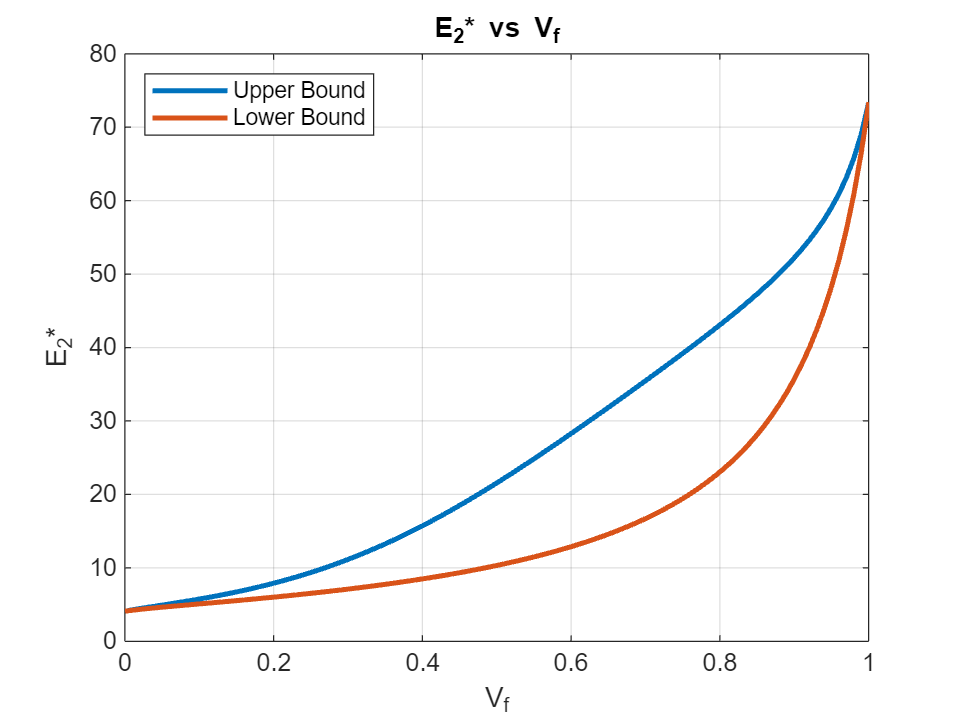


plot(Vf_val, E2_plus, 'LineWidth', 2)
hold on;
plot(Vf_val, E2_minus, 'LineWidth', 2)
title('E_2* vs V_f');
xlabel('V_f'); ylabel('E_2*');
legend('Upper Bound', 'Lower Bound', 'Location', 'northwest')
grid on
hold off;

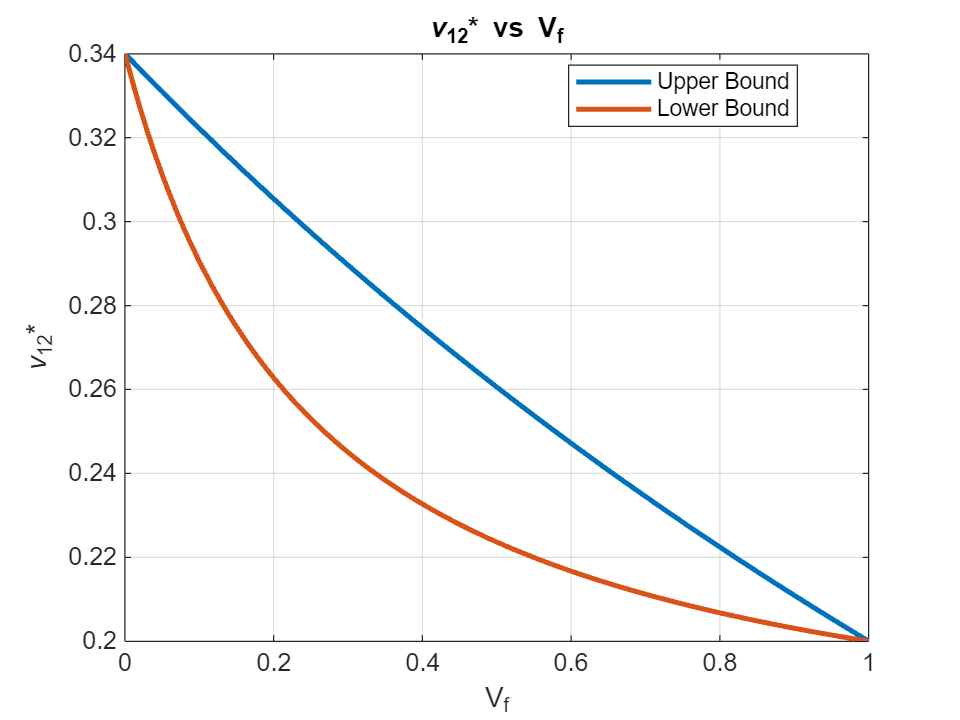


plot(Vf_val,v12_plus, 'LineWidth', 2)
hold on;
plot(Vf_val,v12_minus, 'LineWidth', 2)
title('\nu_{12}* vs V_f');
xlabel('V_f'); ylabel('\nu_{12}*');
legend('Upper Bound', 'Lower Bound', 'Location', 'best')
grid on
hold off;

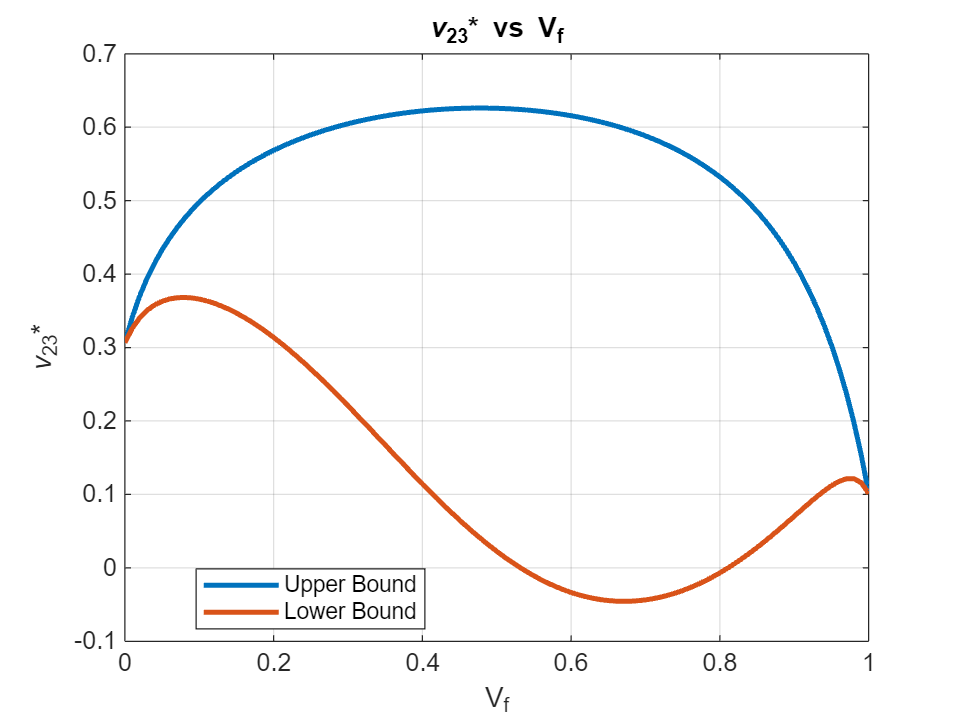


figure;
plot(Vf_val, v23_plus, 'LineWidth', 2)
hold on;
plot(Vf_val, v23_minus, 'LineWidth', 2)
title('\nu_{23}* vs V_f');
xlabel('V_f'); ylabel('\nu_{23}*');
legend('Upper Bound', 'Lower Bound', 'Location', 'best')
grid on
hold off;

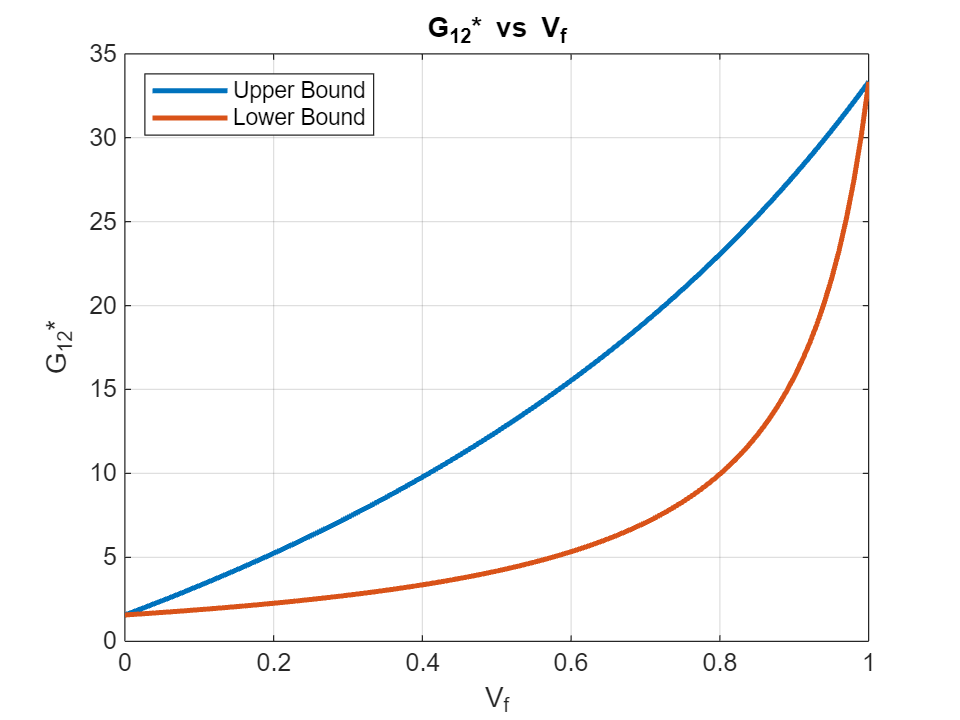


plot(Vf_val,G12_plus, 'LineWidth', 2)
hold on;
plot(Vf_val,G12_minus, 'LineWidth', 2)
title('G_{12}* vs V_f');
xlabel('V_f'); ylabel('G_{12}*');
legend('Upper Bound', 'Lower Bound', 'Location', 'northwest')
grid on
hold off;

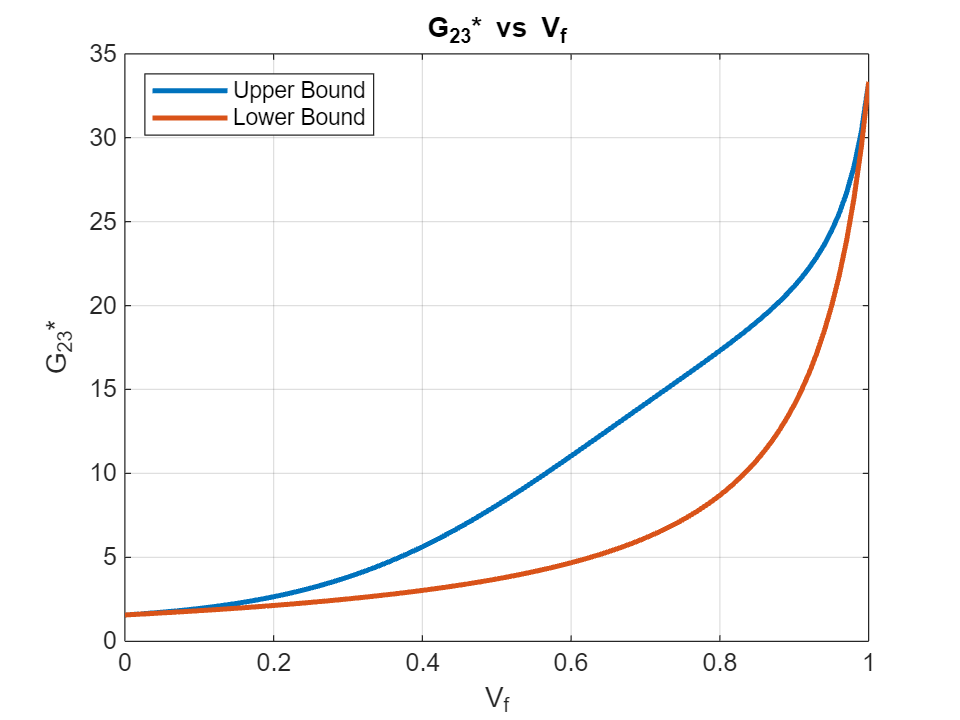


plot(Vf_val,G23_plus, 'LineWidth', 2)
hold on;
plot(Vf_val,G23_minus, 'LineWidth', 2)
title('G_{23}* vs V_f');
xlabel('V_f'); ylabel('G_{23}*');
legend('Upper Bound', 'Lower Bound', 'Location', 'northwest')
grid on
hold off;

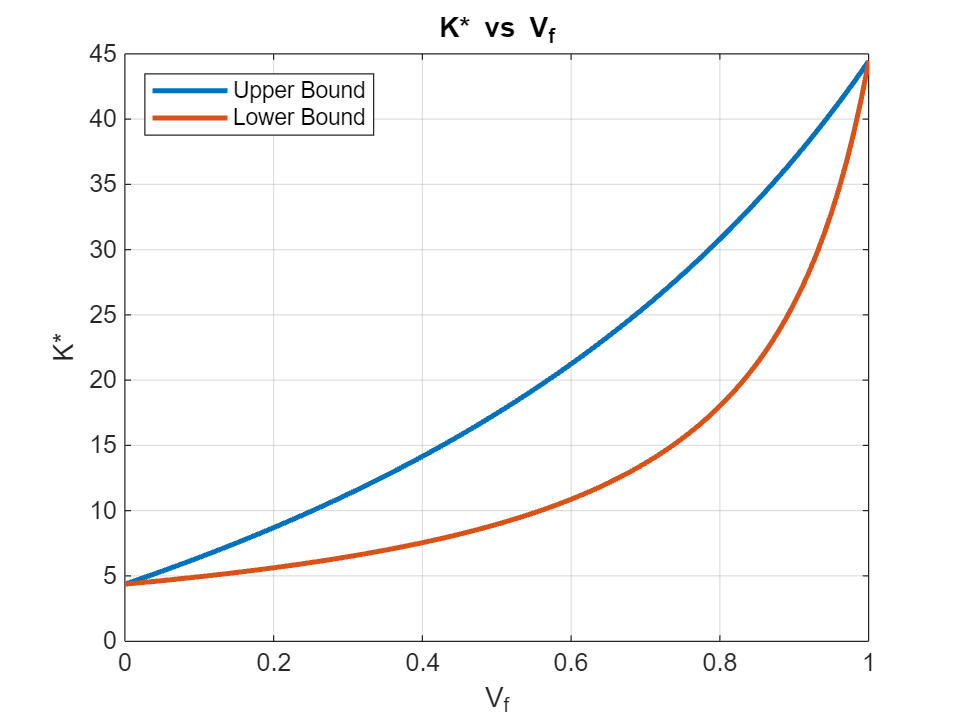


plot(Vf_val,K_plus, 'LineWidth', 2)
hold on;
plot(Vf_val,K_minus, 'LineWidth', 2)
title('K* vs V_f');
xlabel('V_f'); ylabel('K*');
legend('Upper Bound', 'Lower Bound', 'Location', 'northwest')
grid on
hold off;